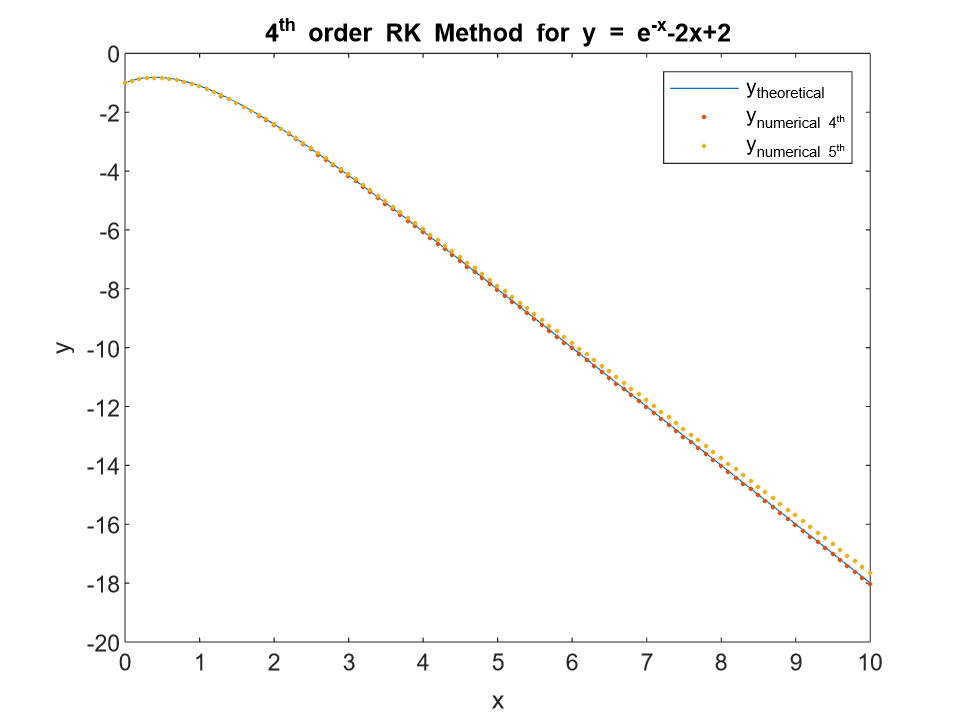

clc
clear
h = .1;  n = 100;

k1 = zeros(1,n); k2 = zeros(1,n); k3 = zeros(1,n);
k4 = zeros(1,n); k5 = zeros(1,n); k6 = zeros(1,n);

yNumericalFourth = zeros(1,n); yNumericalFourth(1) = -1;
yNumericalFifth = zeros(1,n); yNumericalFifth(1) = -1;

x(1) = 0; x = x(1):h:x(1)+h*n;

syms X Y;
myFunction = -2*X-Y;
yTheoretical = -3.*exp(-x)-2.*x+2;

for i=1:n

    k1(i) = h*subs(myFunction , [X,Y],[x(i) , yNumericalFourth(i)]);
    k2(i) = h*subs(myFunction , [X,Y],[x(i)+h/4 , yNumericalFourth(i)+k1(i)/4]);
    k3(i) = h*subs(myFunction , [X,Y],[x(i)+3*h/8 , yNumericalFourth(i)+3*k1(i)/32+9*k2(i)/32]);
    k4(i) = h*subs(myFunction , [X,Y],[x(i)+12*h/13 , yNumericalFourth(i)+1932*k1(i)/2197-7200*k2(i)/2197+7296*k3(i)/2197]);
    k5(i) = h*subs(myFunction , [X,Y],[x(i)+h , yNumericalFourth(i)+439*k1(i)/216-8*k2(i)+3680*k3(i)/513-845*k4(i)/4104]);
    k6(i) = h*subs(myFunction , [X,Y],[x(i)+h/2 , yNumericalFourth(i)-8*k1(i)/27+2*k2(i)-3544*k3(i)/2565+1859*k4(i)/4104-11*k5(i)/40]);

    yNumericalFourth(i+1) = yNumericalFourth(i) + (25*k1(i)/216 + 1408*k3(i)/2565 + 2197*k4(i)/4104 - k5(i)/5);
    yNumericalFifth(i+1) = yNumericalFifth(i) + (16*k1(i)/165 + 6656*k3(i)/12825 + 28561*k4(i)/56430 - 9*k5(i)/50 + 2*k6(i)/55);
end

error = yTheoretical - yNumericalFourth;
errorPercentage = error./yTheoretical;

plot(x,yTheoretical,x,yNumericalFourth,'.',x,yNumericalFifth,'.')
title("4^{th} order RK Method for y = e^{-x}-2x+2")
xlabel("x"), ylabel("y")
legend("y_{theoretical}","y_{numerical 4^{th}}", "y_{numerical 5^{th}}")